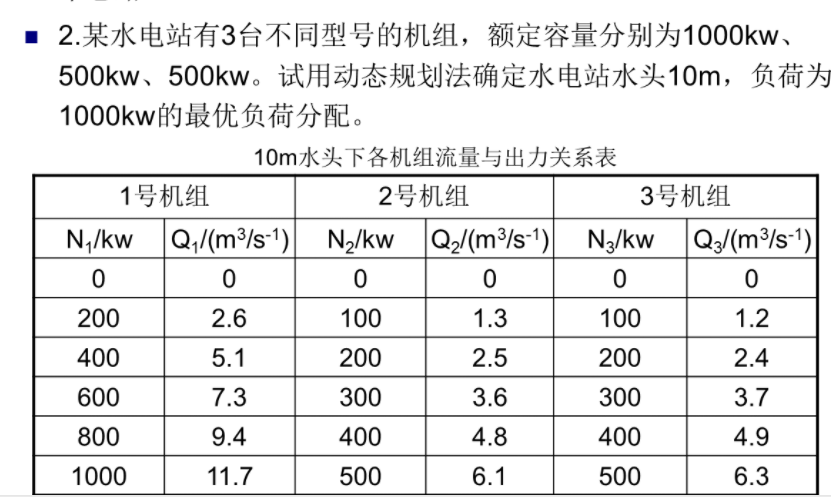

clc;clear
N_Q=[0 inf 2.6 inf 5.1 inf 7.3 inf 9.4 inf 11.7
    0 1.3 2.5 3.6 4.8 6.1 inf inf inf inf inf 
    0 1.2 2.4 3.7 4.9 6.3 inf inf inf inf inf];
N=1000;  %需要产生的最大负荷
step_size=100;  %发电机发电步长
[row,col]=size(N_Q);
N_Q=[N_Q,inf(row,N/step_size-col+1)];  %拓展用的，此题中没有使用到
[row,col]=size(N_Q);  
stage=row;  %阶段数，此题分为3个阶段数

%choose是用来记录动态规划中最优路径的
%其中2行为一个阶段，所以有stage*2行，偶数行为在此阶段包括此阶段之前的负荷量
...奇数行为此时对应阶段的某一个已分配负荷的最优Q值
%在以电定水中，水最小为目标值，电为约束条件，所以少数情况下可能满足最少用水
...发电分配不同，即少数情况下有多个最优解，此时choose的偶数行为多个值
choose=strings(stage*2,col);
choose(1,:)=N_Q(1,:);
choose(2,:)=0:step_size:N;
count=3;

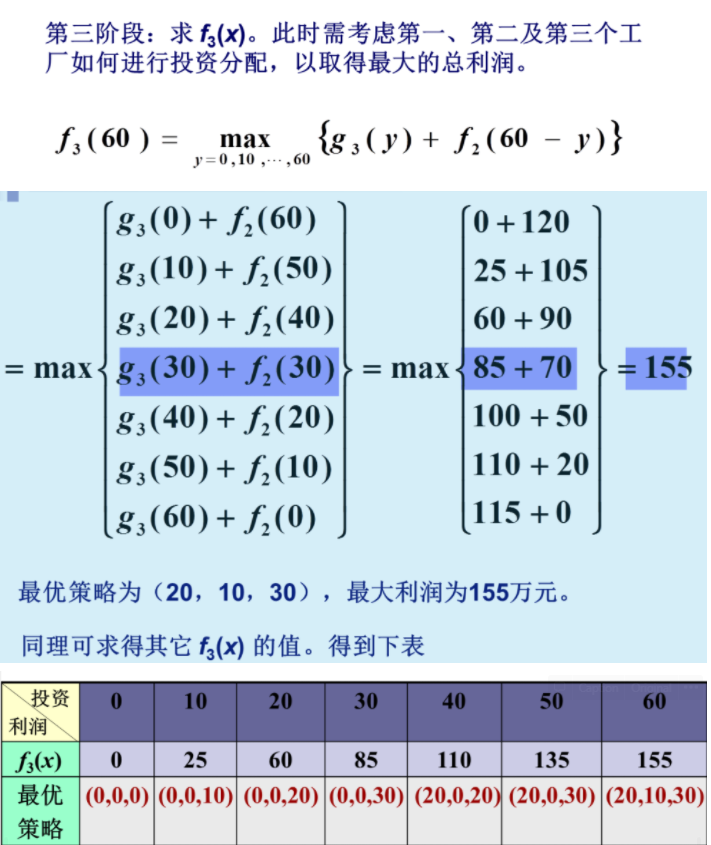

f=N_Q(1,:);%f表示以负荷x分配给前k个发电机，所得到的的最小用水量
%%动态规划的3层循环
for i=2:stage  %第一层循环为stage阶段循环
    f_next=zeros(col,1);
    for x=N:-step_size:0 %第二层循环为x状态循环
        storage=zeros(x/step_size+1,1);%类似于上图中的大括号的大小空间
        for y=0:step_size:x %第二层循环为循环
            %状态转移方程N_Q为此阶段分配负荷y所对应的Q，
            ...f(x-y)为此阶段前所有阶段分配(x-y)时的最优Q
            storage(y/step_size+1)=N_Q(i,y/step_size+1)+f((x-y)/step_size+1);
        end
        temp_max=min(storage);
        temp_num=find(storage==temp_max)';
        %记录路径choose
        choose(count,x/step_size+1)=num2str(temp_max);
        choose(count+1,x/step_size+1)=num2str((temp_num-1)*step_size);
        %记录特定x下，遍历的不同y对应的f值，记做f_next
        f_next(x/step_size+1)=temp_max;
    end
    count=count+2;
    %交换f_next,上一阶段的结果是下一阶段的开始
    f=f_next;
end
disp("注意结果顺序为最后一台发电机负荷，倒数第二台发电机负荷...第一台发电机负荷:")

注意结果顺序为最后一台发电机负荷，倒数第二台发电机负荷...第一台发电机负荷:


MYFUN(N,step_size,row*2,col,choose);

Generator_load = 0

Generator_load = 0

Generator_load = 1000

result_value=str2double(choose(row*2-1,col))

result_value = 11.7000